% generate some fake data
x = [2.5 2.8 3.4 2 1.2 2.1 1.8 2.8 1.1 2.2 3.2 0.61 3 0.53 2 0.45 2 ...
1 -0.53 1.2 2.2 2.5 1.9 1.9 2.8 2.8 1.3 3.1 2.7 2.3 0.47 2.1 1.5 3.8 ...
3 2.8 0.97 2.5 2.3 3.9 0.54 3.6 2.3 2.7 4.4 2.7 0.44 2.1 1.7 2.1].^2;

y = [5.9 6.4 3.7 3.1 5.1 3.6 6.2 5.1 3 4.7 6 1.2 6.1 -0.51 4.4 3 ...
5.1 2.2 0.14 3.2 7.2 7.4 4 4.5 5.3 2 4.9 3 4.6 3.9 3.5 4.2 3.6 5.4 ...
4.5 6.1 2.6 4.9 3.5 4.8 1 6.8 4.2 3.7 7.5 1.7 2.8 1.8 3.6 4.3].^2;

% compute the actual correlation value observed
actualcorr = corr(x(:), y(:));

% draw bootstrap samples and compute correlation values
results = zeros(1, 10000);
for num=1 : 10000
    
    % ix - is a column of indices (each element is a random integer between
    % 1 and n where n is the number of data points);
    % ix will be used as an array of indexes to select values for each bootstrap
    % samples;
    % rand(1, length(x)) generates a column with values between [0,1];
    % ceil(vector) - round the double values to the nearest greater or equal
    % integer;
    ix = ceil(length(x) * rand(1, length(x)));
    
    % randomly chosen sub-samples of x and y using ix indexes vector;
    % sub-samples are transposed to a column-vector
    x_ix = x(ix)';
    y_ix = y(ix)';
    
    % compute correlation using selected data points
    % the num-th step
    results(num) = corr(x_ix, y_ix);
    
end

% MATLAB's bootstrp.m function can be used to achieve the same results:
   results2 = bootstrp(10000, @(x0,y0) corr(x0,y0), x', y');

% the central 95% of the bootstrap results
ptiles = prctile(results, [2.5 97.5]);
ptiles2 = prctile(results2, [2.5 97.5]);

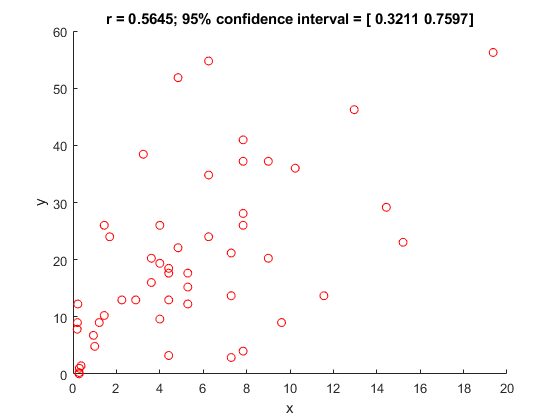

% visualize
figure; 
hold on;
scatter(x,y,'ro');

xlabel('x');
ylabel('y');

title(sprintf('r = %.4f; 95%% confidence interval = [ %.4f %.4f]', actualcorr, ptiles(1), ptiles(2)));

disp('The output for MATLAB bootstrap.m function');

The output for MATLAB bootstrap.m function


fprintf('r = %.4f; 95%% confidence interval = [ %.4f %.4f]', actualcorr, ptiles2(1), ptiles2(2));

r = 0.5645; 95% confidence interval = [ 0.3204 0.7534]